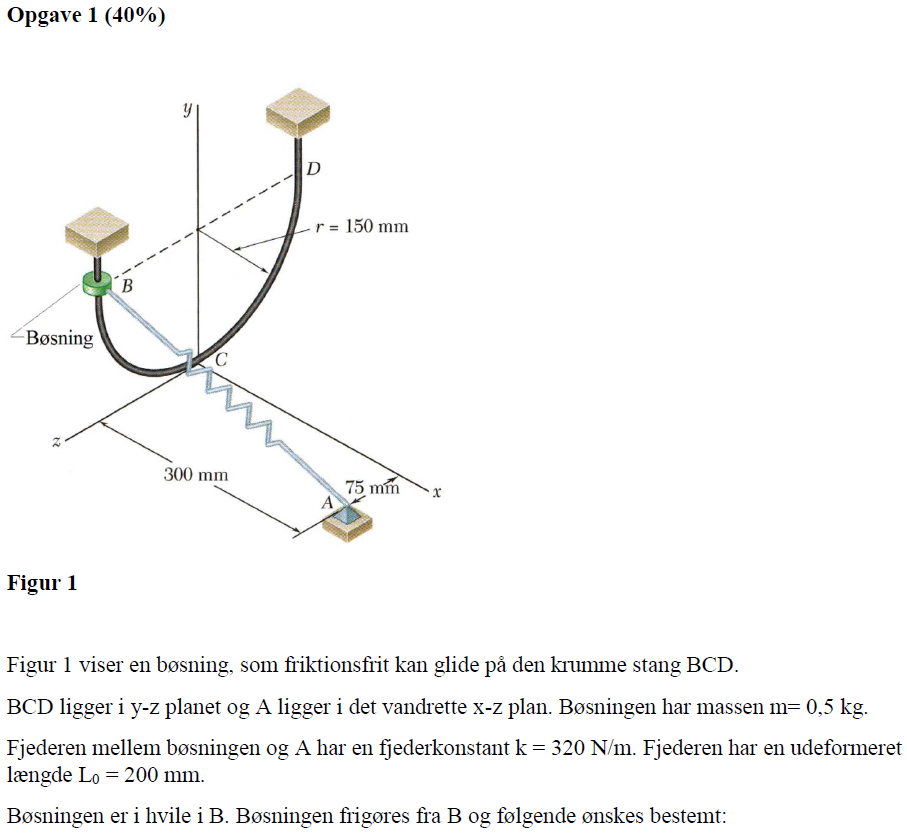

clear all
format shortg
r = 0.150

r =          0.15


m_b = 0.5; % kg
k = 320; %N/m
L_0 = 0.2; %m

L_AB = 0.34369; % m
L_AC = 0.30923; % m

Vi opstiller koordinaterne for punkterne

A = [0.3; 0; 0.075];
B = [0; 0.150; 0.150];
C = [0; 0; 0];

Vectoren imellem punkterne er

L_AB_vec = B - A % forskellen i de to punkter giver vektoren imellem dem

L_AB_vec =          -0.3
         0.15
        0.075


L_AC_vec = C - A % forskellen i de to punkter giver vektoren imellem dem

L_AC_vec =          -0.3
            0
       -0.075


Længden findes med pythagoras sætning for 3d

L_AB_test = norm(L_AB_vec)

L_AB_test =       0.34369


L_AC_test = norm(L_AC_vec)

L_AC_test =       0.30923


Hvilket var resultaterne vi ledte efter

b) Bøsningens hastighed vc når den passerer C

Det antages at vi har en masseløs fjeder. Dermed har vi kun en energi ændring fra punkt B til punkt C gævet ved vændringen i fjeder energien og potentiel energi.

syms v_C

V_fjeder_B = k * (L_AB - L_0)^2 / 2

V_fjeder_B =        3.3035


V_fjeder_C = k * (L_AC - L_0)^2 / 2

V_fjeder_C =         1.909



g = 9.81; % m/s^2
h_B = 0.150;
h_C = 0;
V_tyngde_B = m_b * g * h_B

V_tyngde_B =       0.73575


V_tyngde_C = m_b * g * h_C

V_tyngde_C =      0



T_B = 0; % starter i hvile
T_C = m_b /2 * v_C^2

$$T\_C = \frac{{v_{C}}^{2}}{4}$$

Vi løser nu for hastigheden i punkt C  ($v_C$) med energi ligningen 

eq = T_B + V_fjeder_B + V_tyngde_B == T_C + V_tyngde_C + V_fjeder_C;

eq_sol = solve(eq, v_C);
v_C = vpa(eq_sol(2), 5)

$$v\_C = 2.9191$$

Således er hastigheden i C $2,92$ m/s^2

c) Kraften F, som stangen påvirker bøsningen med i C

I C påvirker stangen kun med krafter i y og x retningen

x - retningen

Her er kraften i stangen en reaktions kraft på fjederens x komposant.

Kraften afjederen beskrives som

F_fjeder_B = k * (L_AC - L_0)

F_fjeder_B =        34.954


% tan(v) = a/b = modstående / hoslæggende
theta = atan(0.075 / 0.3)

theta =       0.24498


F_fjeder_Bx = F_fjeder_B * cos(theta)

F_fjeder_Bx =         33.91


F_stang_x = -F_fjeder_Bx;

y-retningen har vi en radial acceleration der giver anledning til en kraft i y-retningen

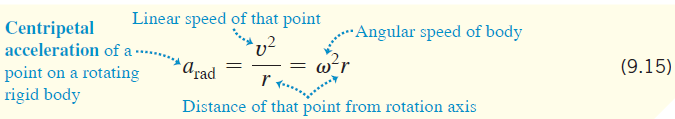

a_rad = v_C^2 / r

$$a\_rad = 56.806658986659792923916992825511$$

F_y_rad = m_b * a_rad

$$F\_y\_rad = 28.403329493329896461958496412756$$

F_y_tyngde = m_b * g

F_y_tyngde =         4.905


F_stang_y = F_y_rad + F_y_tyngde;

F_vec = [F_stang_x; F_stang_y];
F_vec_ = vpa([F_stang_x; F_stang_y],5)

$$F\_vec\_ = \left(\begin{array}{c} -33.91\\ 33.308 \end{array}\right)$$

F = norm(F_vec)

$$F = 47.532421306363529749828135151006$$

Således er den totale kraft som stangen optager $F = 47,53$N

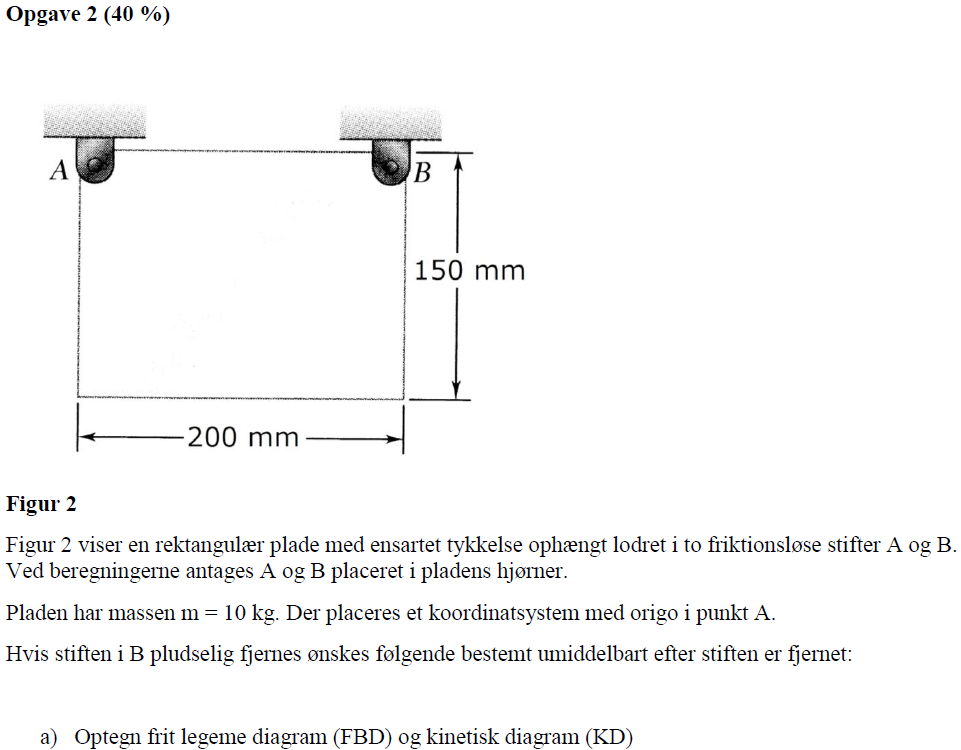

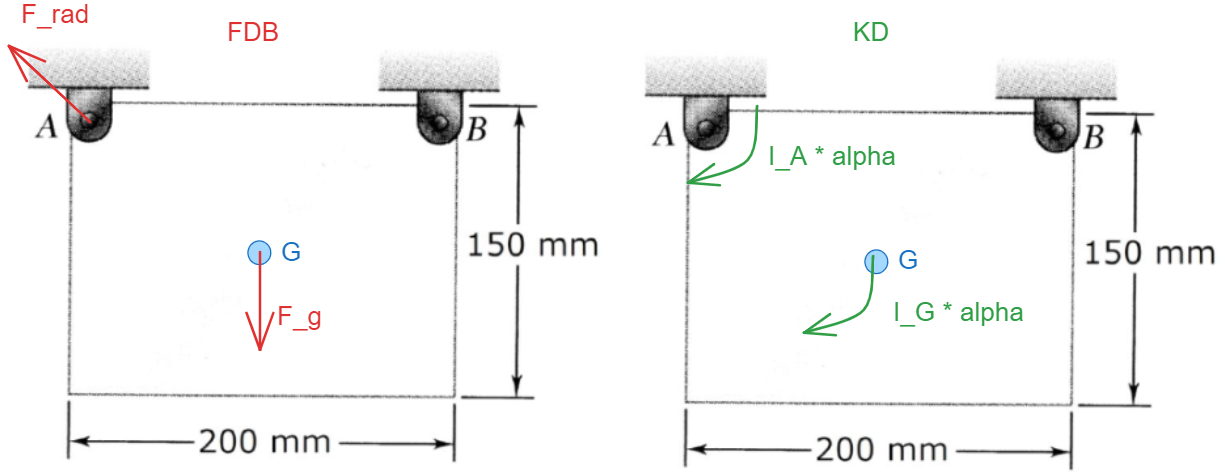

clear all
format shortg
m = 10; %kg
h = 0.15; %m
b = 0.20; %m
g = 9.81; %m/s^2

b) Bestem pladens masseinertimoment om tyngdepunktet IG

Vi slå inertimomentet for en plade op til


$$I_G = \frac{m (h^2 + b^2)}{12}$$


I_G = m * (h^2 + b^2) / 12 % tabel D/4

I_G =      0.052083


således får vi et intertimoment på $0,052$kg m^2

c) Bestem pladens masseinertimoment IA om punkt A

Vi flytter I_G op til A

d = sqrt(((h/2)^2 + (b/2)^2))

d =         0.125


I_A = I_G + m * d^2

I_A =       0.20833


d) Bestem pladens vinkelacceleration α – resultatet ønskes anført som αk

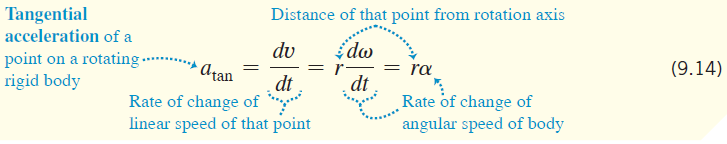

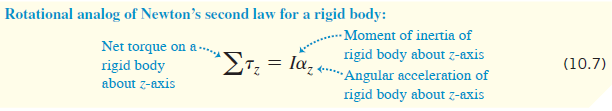

a_tan = g;
syms alpha
tau_tan = b/2 * g * m

tau_tan =          9.81



eq_tau = tau_tan == I_A * alpha;

eq_sol = solve(eq_tau, alpha)

$$eq\_sol = \frac{5886}{125}$$

alpha = double(vpa(eq_sol(1), 5))

alpha =        47.088


således er vinkelaccelerationen


$$\bar{\alpha} = 47,088 \bar{k}$$


brug ikke dette:


$$\alpha k = d i \cdot F j \\
\left[\matrix{ 0 \cr 9,81 \cr 0} \right] =  \left[\matrix{ 0,1 \cr 0,075 \cr 0} \right] \times \left[\matrix{ 0 \cr 0 \cr -47,09} \right] $$


e) Bestem reaktionskraften FA i A - anført som FAx i og FAyj

% a_tan = double(alpha * d)
F_g = m * g

F_g =          98.1


theta = atan( (h/2) / (b/2) );
rad2deg(theta)

ans =         36.87


A_t = F_g * cos(theta) - m * d * alpha % m * d * alpha = a_tan * m

A_t =         19.62


A_n = F_g * sin(theta)

A_n =         58.86


FA_i = A_t * sin(theta) - A_n * cos(theta)

FA_i =       -35.316


FA_j = A_t * cos(theta) + A_n * sin(theta)

FA_j =        51.012



$$F_A = F_A i + F_A j + F_A k = -35,3i + 51,0j + 0 k\\
\bar{F_A} = \left[\matrix{ -35,3 \cr 51 \cr 0} \right] $$


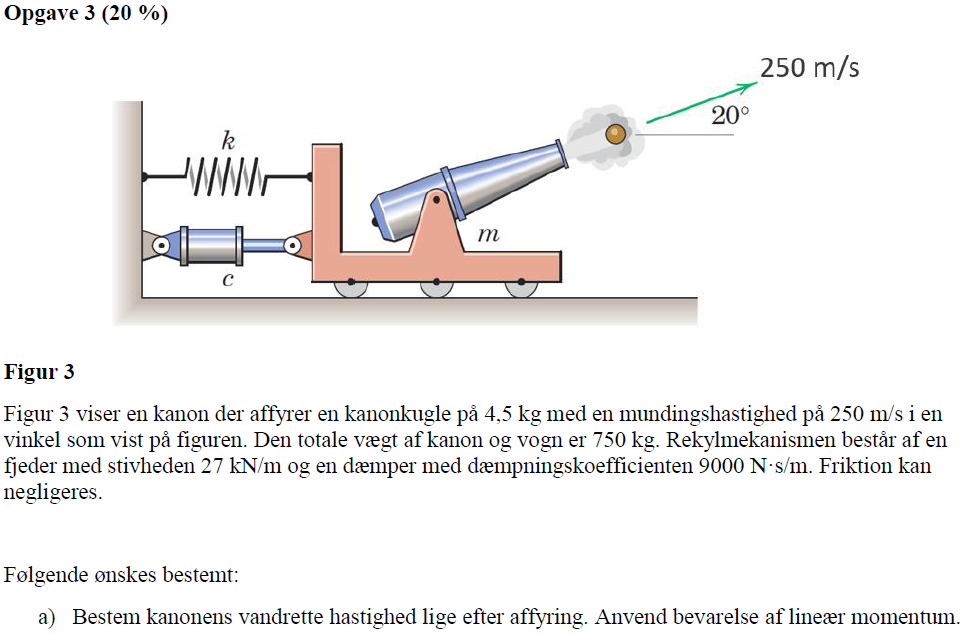

clear all
m_kugle = 4.5; %kg
v_kugle = 250; %m/s
theta = 20;
m_kanon = 750; %kg
k = 27000; %N/m
c = 9000; %N s / m

v_kanon = m_kugle * v_kugle / m_kanon

v_kanon =    1.500000000000000


Vi finder nu den vanrette hasigtehed

v_x = v_kanon * cosd(theta)

v_x =    1.409538931178863


Den vandrette hastighed $v_x$ er således 1,41 m/s

b) Bestem systemets cykliske egenfrekvens og dæmpningsforholdet.

w_n = sqrt(k/m_kanon) %egensvingningen

w_n =      6


format long
zeta = c/(2 * m_kanon * w_n) % viscous damping factor or damping ratio

zeta =      1


systemet er således critisk dæmpede.

c) Bestem kanonens største vandrette flytning.

syms A_1 A_2 t 
t_0 = 0;
x_0 = 0;
v_0 = v_x;
x = (A_1 + A_2 * t) * exp(-w_n * t)

$$x = {\mathrm{e}}^{-6\,t}\,\left(A_{1}+A_{2}\,t\right)$$

v = diff(x, t)

$$v = A_{2}\,{\mathrm{e}}^{-6\,t}-6\,{\mathrm{e}}^{-6\,t}\,\left(A_{1}+A_{2}\,t\right)$$


[sol_A_1, sol_A_2] = solve([x == x_0, v == v_0], [A_1, A_2]);
A_1 = subs(sol_A_1, t, t_0)

$$A\_1 = 0$$

A_2 = subs(sol_A_2, t, t_0)

$$A\_2 = \frac{6347999005221333}{4503599627370496}$$

x(t) = (A_1 + A_2 * t) * exp(-w_n * t);
v(t) = diff(x(t), t)

$$v(t) = \frac{6347999005221333\,{\mathrm{e}}^{-6\,t}}{4503599627370496}-\frac{19043997015663999\,t\,{\mathrm{e}}^{-6\,t}}{2251799813685248}$$


t_max_eq = 0 == v(t);
t_max = solve(t_max_eq, t)

$$t\_max = \frac{1}{6}$$

x_max = vpa(x(t_max), 5)

$$x\_max = 0.086423$$

Således er den maximale forskydning 0,0864m = 86,4mm

Vi kontrollere med plots

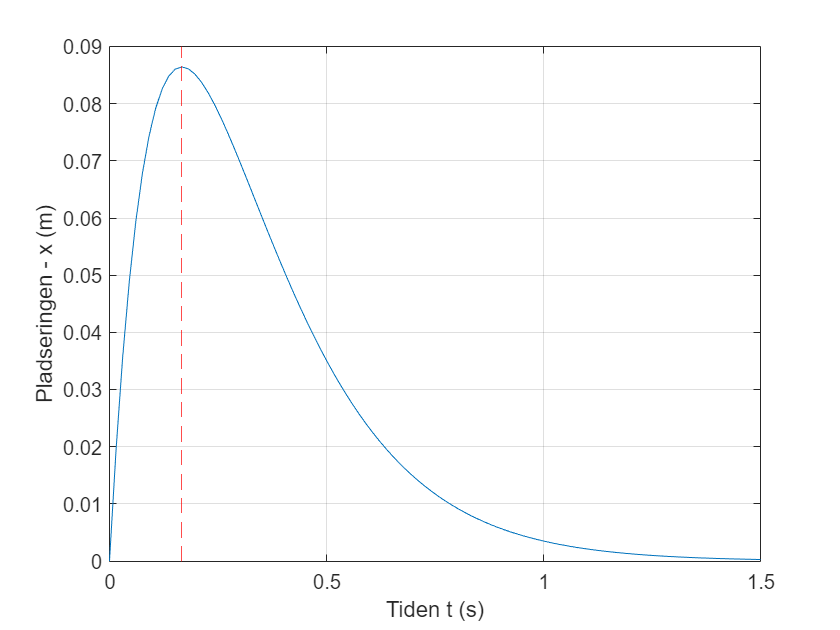

t_lin = linspace(0, 1.5,100);

plot(t_lin, x(t_lin))
yline(0, '--')
xline(double(t_max), 'r--')
ylabel('Pladseringen - x (m)')
xlabel('Tiden t (s)')
grid('on')

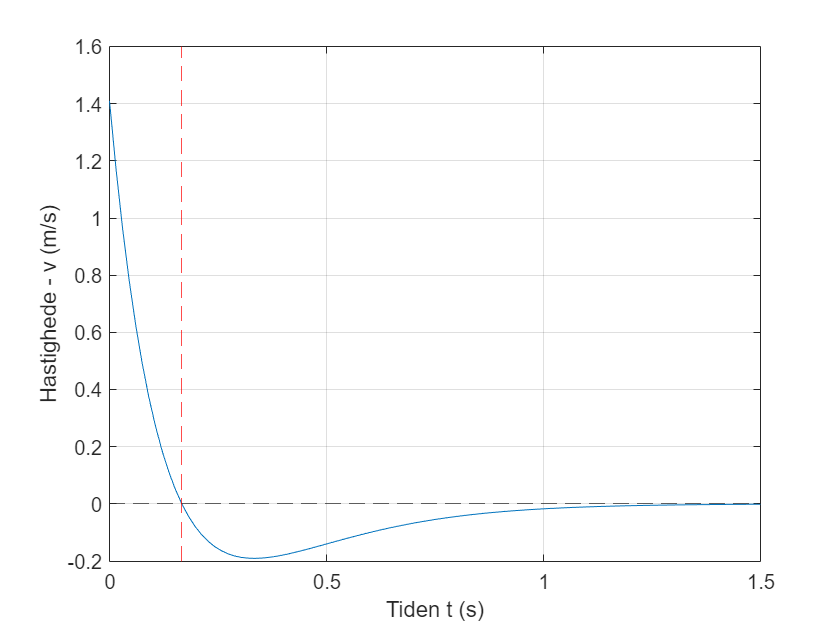

plot(t_lin, v(t_lin))
yline(0, '--')
xline(double(t_max), 'r--')
ylabel('Hastighede - v (m/s)')
xlabel('Tiden t (s)')
grid('on')